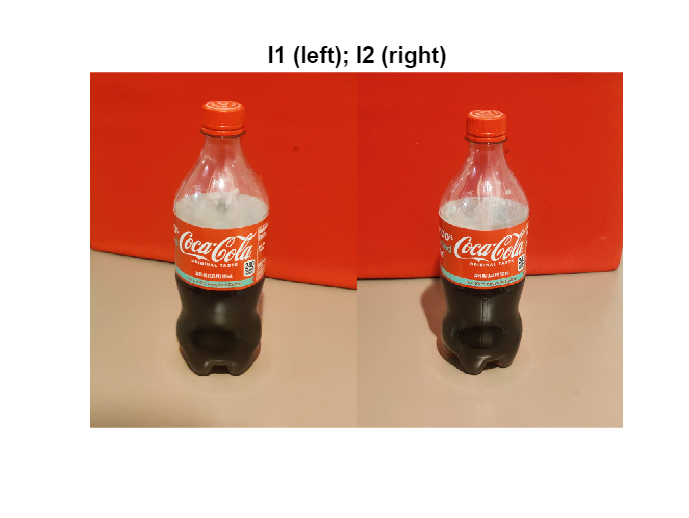

% Read in two color images of the same scene, which were taken from different positions. 
% Then, convert them to grayscale.

I1 = imread("image-1.jpg");
I2 = imread("image-2.jpg");

% Convert to grayscale.
I1gray = rgb2gray(I1);
I2gray = rgb2gray(I2);

% Display both images side by side.
figure
imshowpair(I1,I2,"montage")
title("I1 (left); I2 (right)")

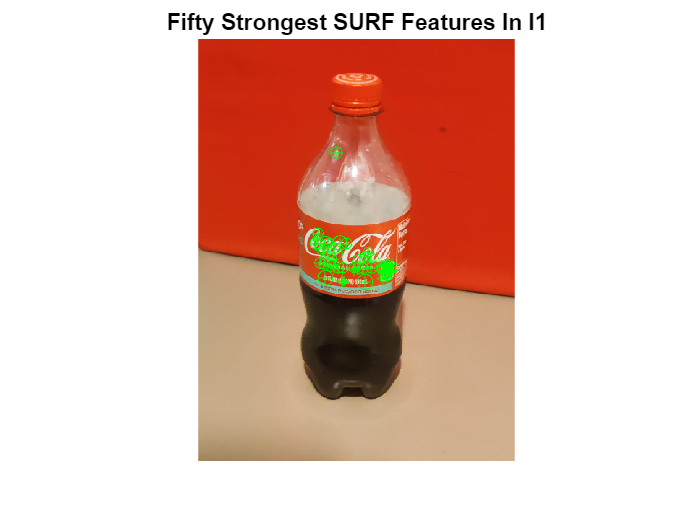


% Detect SURF features.
blobs1 = detectSURFFeatures(I1gray, 'MetricThreshold', 1000);
blobs2 = detectSURFFeatures(I2gray, 'MetricThreshold', 1000);

% Visualize SURF features.
figure 
imshow(I1)
hold on
plot(selectStrongest(blobs1, 50))
title("Fifty Strongest SURF Features In I1")

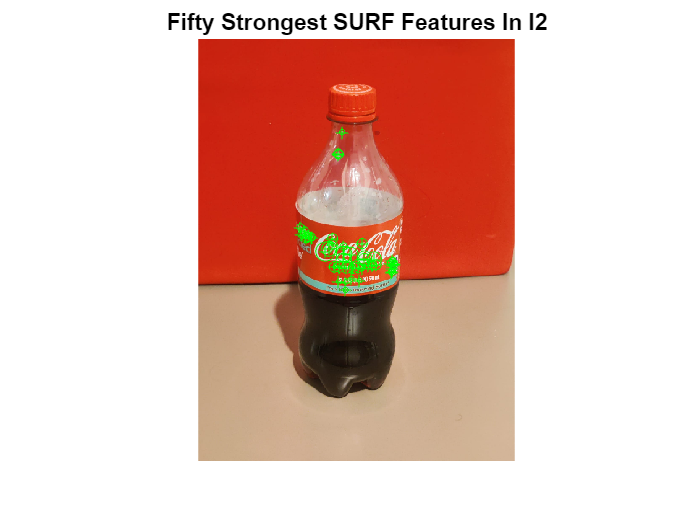


figure
imshow(I2)
hold on
plot(selectStrongest(blobs2, 50))
title("Fifty Strongest SURF Features In I2")

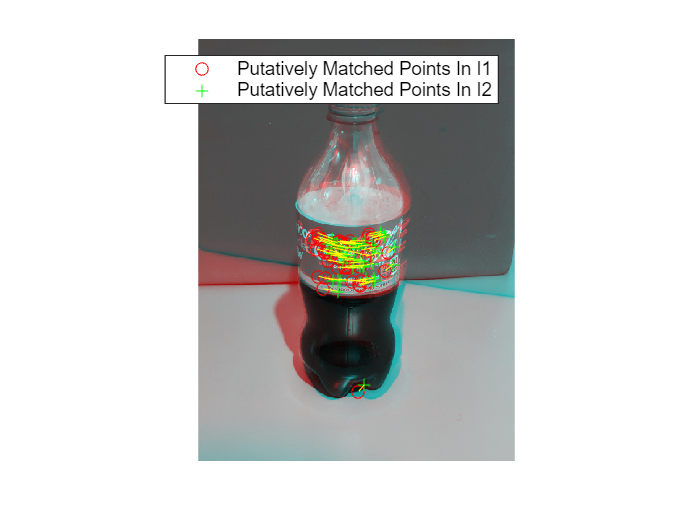


% Extract features and match them.
[features1, validBlobs1] = extractFeatures(I1gray, blobs1);
[features2, validBlobs2] = extractFeatures(I2gray, blobs2);
indexPairs = matchFeatures(features1, features2, 'Metric', 'SAD', 'MatchThreshold', 10);

matchedPoints1 = validBlobs1(indexPairs(:,1), :);
matchedPoints2 = validBlobs2(indexPairs(:,2), :);

figure 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2)
legend("Putatively Matched Points In I1", "Putatively Matched Points In I2")

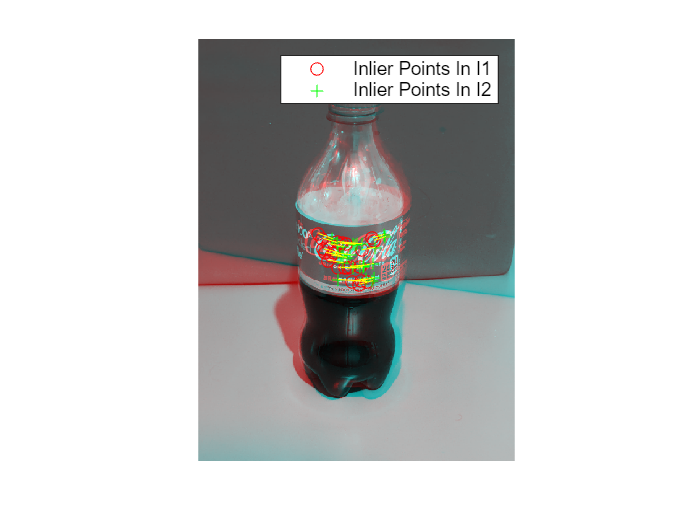


% Estimate fundamental matrix.
[fMatrix, epipolarInliers] = estimateFundamentalMatrix(...
  matchedPoints1, matchedPoints2, 'Method', 'RANSAC', ...
  'NumTrials', 10000, 'DistanceThreshold', 0.1, 'Confidence', 99.99);

% Check if enough inliers were found.
if numel(epipolarInliers) < 30
    error("Not enough matching points were found");
end

inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2)
legend("Inlier Points In I1", "Inlier Points In I2")

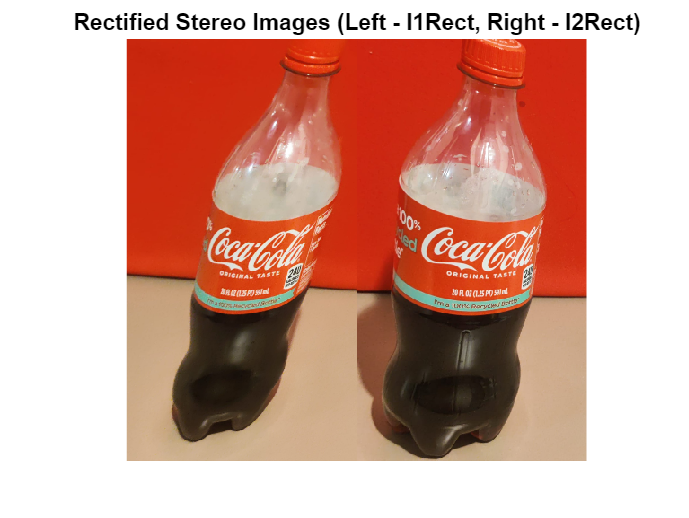


% Estimate rectification transforms.
[tform1, tform2] = estimateStereoRectification(fMatrix, ...
  inlierPoints1.Location, inlierPoints2.Location, size(I2));

[I1Rect, I2Rect] = rectifyStereoImages(I1, I2, tform1, tform2);
figure
imshowpair(I1Rect, I2Rect, 'montage')
title("Rectified Stereo Images (Left - I1Rect, Right - I2Rect)")